# Train YOLOv2 Network for Fire Detection

In this example, I've used Fismo dataset [1], and you can download dataset with in [here](https://github.com/mtcazzolato/dsw2017). Download the dataset Part 2, Fismo-Images.zip in the link and unzip into your current directory. Typically, I've used the part of dataset in this path from dataset 'FiSmo-Images\Flickr-Fire\Flickr-Fire_flame'.

Access data using imageDatastore for data ground truth labeling.

imds = imageDatastore("FiSmo-Images\Flickr-Fire\Flickr-Fire_flame");

#### Label your data with automated algorithm

First of all, label data with Image Labeler with automated algorithm 'FireDetection.m'.

You can import your custom algorithm for labeling automation. In this example, 'FireDetection.m' is pre-built custom algorithm, so you can just put the code into the Image labeler app. [Details of image labeler](https://kr.mathworks.com/help/releases/R2019b/vision/ug/get-started-with-the-image-labeler.html) and [importing custom algorithm](https://www.mathworks.com/help/releases/R2019b/vision/ug/create-automation-algorithm-for-labeling.html#bvkyuip-4) is describe in the links. Also you can follow up below steps for automation

- Launch the imageLabeler app

- Create Label definition and name it 'Fire' (Watch out for the typo).

- Load imagedatastore created in above section by, Load -> Add images from Datastore -> Select imds.

- Import custom algorithm for labeling automation by Select Algorithm -> Add Algorithm -> Import Algorithm ('FireDetection.m')

- Select all the images listed in the app and select Fire Detection Algorithm -> Automate.

- Fine tune after labeling done, export label data to the workspace (gTruth).

imageLabeler

#### Create table data format from auto-labeled ground truth data

trainingdata = gTruth.LabelData;
trainingdata.files = gTruth.DataSource.Source;
trainingdata = trainingdata(:, [2, 1]);

#### Create YOLOv2 network

Inspect the layers in the YOLO v2 network and their properties. [Create YOLO v2 Object Detection Network](docid:vision_ug#mw_4f6ea50f-8a93-4102-81a3-b2ba83bf7d58). 

YOLO v2 transform layer : The number of channels must equal numAchors * (5+numClasses).

layers = [
    imageInputLayer([128 128 3],"Name","input","Normalization","none")
    

ans =   다음 계층을 포함한 25x1 Layer 배열:

     1   'input'               이미지 입력                    128x128x3 이미지
     2   'conv_1'              컨벌루션                      16개 3x3 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     3   'BN1'                 배치 정규화                    배치 정규화
     4   'relu_1'              ReLU                      ReLU
     5   'maxpool1'            최댓값 풀링                    2x2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv_2'              컨벌루션                      32개 3x3 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     7   'BN2'                 배치 정규화                    배치 정규화
     8   'relu_2'              ReLU                      ReLU
     9   'maxpool2'            최댓값 풀링                    2x2 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv_3'              컨벌루션                      64개 3x3 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'BN3'                 배치 정규화          

    convolution2dLayer([3 3],16,"Name","conv_1","Padding",[1 1 1 1],"WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","BN1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool1","Stride",[2 2])
    
    convolution2dLayer([3 3],32,"Name","conv_2","Padding",[1 1 1 1],"WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","BN2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool2","Stride",[2 2])
    
    convolution2dLayer([3 3],64,"Name","conv_3","Padding",[1 1 1 1],"WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","BN3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([2 2],"Name","maxpool3","Stride",[2 2])
    
    convolution2dLayer([3 3],128,"Name","conv_4","Padding",[1 1 1 1],"WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","BN4")
    reluLayer("Name","relu_4")
    
    convolution2dLayer([3 3],128,"Name","yolov2Conv1","Padding","same","WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","yolov2Batch1")
    reluLayer("Name","yolov2Relu1")
    
    convolution2dLayer([3 3],128,"Name","yolov2Conv2","Padding","same","WeightsInitializer","narrow-normal")
    batchNormalizationLayer("Name","yolov2Batch2")
    reluLayer("Name","yolov2Relu2")
    
    convolution2dLayer([1 1],24,"Name","yolov2ClassConv","WeightsInitializer","narrow-normal")
    

detector =   yolov2ObjectDetector - 속성 있음:

            ModelName: 'Fire'
              Network: [1×1 DAGNetwork]
           ClassNames: {'Fire'}
          AnchorBoxes: [4×2 double]
    TrainingImageSize: [128 128]


    yolov2TransformLayer(4,"Name","yolov2Transform")
    yolov2OutputLayer([8 8;32 48;40 24;72 48],"Name","yolov2OutputLayer")
    ];
lgraph = layerGraph;
lgraph = addLayers(lgraph, layers);
lgraph.Layers

#### Configure the network training options.

- Set the solver to use adam solver for training.

- Set the initial learning rate to use for training.

- Set the verbose indicator to display training progress information in the command window.

- Set the size of mini-batch to use for each training iteration. Reduce the size of mini-batch to reduce memory usage during training.

- Set the maximum number of epoch for training.

- Specify the network to shuffle the training data before each epoch.

- Specify the frequency of verbose printing.

- Specify the path for saving the checkpoint networks. You can use this option to resume training from any saved checkpoint networks.

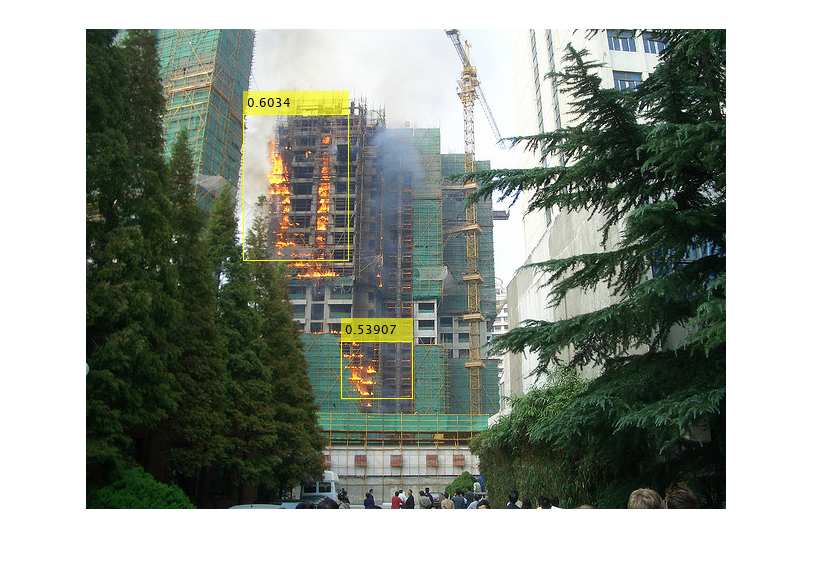

options = trainingOptions('adam',...
          'InitialLearnRate',0.001,...

          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','every-epoch',...
          'VerboseFrequency',30);

Train the YOLO v2 network.

doTrain = true;
if doTrain
      [detector,info] = trainYOLOv2ObjectDetector(trainingdata,lgraph,options);
      detector

   You can verify the training accuracy by inspecting the training loss for each iteration.

        figure
        plot(info.TrainingLoss)
        grid on
        xlabel('Number of Iterations')
        ylabel('Training Loss for Each Iteration')
        save yoloFire detector
else
    % Load if you have trained above detector before
    load yoloFire.mat
end

#### Read a test image into the workspace.

detector
img = imread(trainingdata.files{4});

Run the trained YOLO v2 object detector on the test image for fire detection.

[bboxes,scores] = detect(detector,img);

Display the detection results.

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)

#### Generate CUDA code for accelerating inference speed.

To generate CUDA code for the yolov2_detect.m entry-point function, create a GPU code configuration object for a MEX target and set the target language to C++.

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
codegen -config cfg yolov2_detect -args {ones(128,128,3,'uint8'), double(1)} -report

*[1] *Cazzolato, Mirela T., et al. "FiSmo: A Compilation of Datasets from Emergency Situations for Fire and Smoke Analysis." *Proceedings of the satellite events* (2017).

*Copyright 2019 The MathWorks, Inc.*